sequence = "akiyo";
fileName = sprintf('%s_cif.y', sequence);
nFrames = dir(fileName).bytes/288/352;
k = 75; % Index of "current" image
deltaT = -5; % Temporal distance of "reference" image
blockSize = 8;
searchRadius = 8;
regularization= true;
log10lambda = 3;
verbose = true;

 

fileName = sprintf('%s_cif.y', sequence);
h=k+deltaT;
lambda = 10^log10lambda;

if verbose,
    fprintf('\nMotion estimation\nBlock size:\t%2dx%2d\nSearch radius:\t%2d\nCurr Image:\t%3d\nRef Image:\t%3d\n\n', ...
        blockSize,blockSize,searchRadius,k,h);
    if regularization
        fprintf('Regularized ME with lambda: %6.3f\n',lambda);
    else
        fprintf('Non-regularized ME\n');
    end
end


Motion estimation
Block size:	 8x 8
Search radius:	 8
Curr Image:	 75
Ref Image:	 70



Non-regularized ME


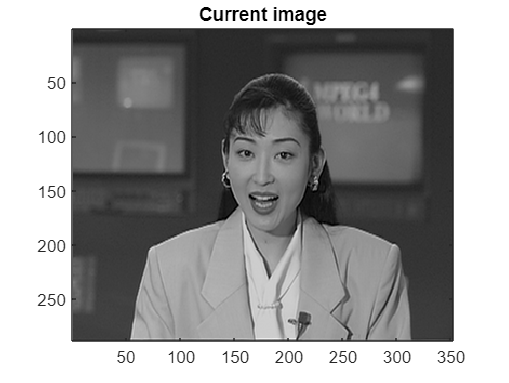

img = readFrame(fileName, k-1 );
reference = readFrame(fileName, h-1 );
figure(2); image(uint8(img));
colormap(gray(256)); axis image; title('Current image');

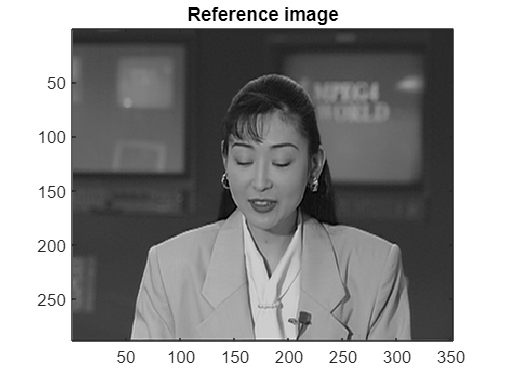

figure(3); image(uint8(reference));
colormap(gray(256)); axis image; title('Reference image');




% Set parameters
params.blockSize = 8;
params.quantizationStep = 30;
params.Searchradius = 7;
params.lambda = 1000; % Adjust lambda value as needed

% Perform block-based intra coding using IntraImgEncoder
[bitstream, imgPSNR, decodedImg] = IntraImgEncoder(img, params);

% Display bitstream and imgPSNR
disp('Bitstream:');

Bitstream:


disp(bitstream);

1111111111111111111110110000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000001111111111111111111110110000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000001111111111111111111110110000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000001111111111111111111011100100000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000001111111111111111111011100100000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000001111111111111111111101100100000000000000100000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000111111111111111111111011000000000000000000000000000000000000000000000000000000000000000000000000000

disp('imgPSNR:');

imgPSNR:


disp(imgPSNR);

   -8.1645



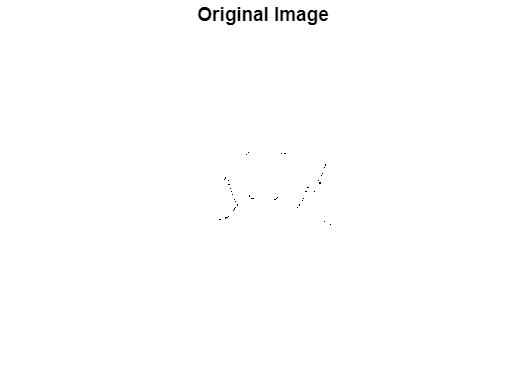


% Display original and decoded images
figure;
imshow(img);
title('Original Image');

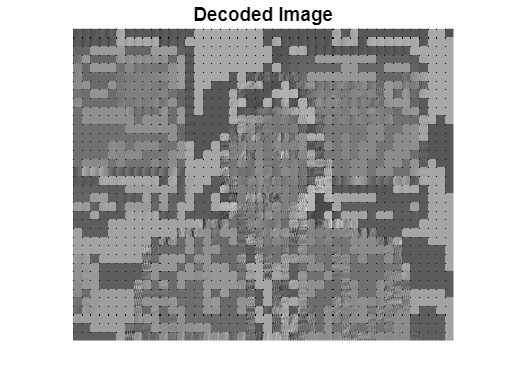

figure;
imshow(uint8(decodedImg));
title('Decoded Image');


[imgBitStream, InterimgPSNR, decodedImg] = InterImgEncoder(img, params);

% Display bitstream and imgPSNR
disp('imgBitStream:');

imgBitStream:


disp(imgBitStream);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

disp('InterimgPSNR:');

InterimgPSNR:


disp(InterimgPSNR);

   15.9473



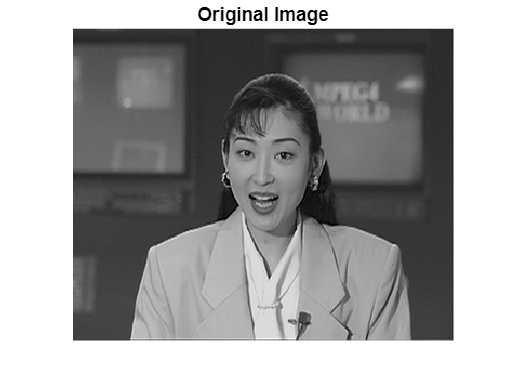


% Display original and decoded images
figure;
imshow(img, []);
title('Original Image');

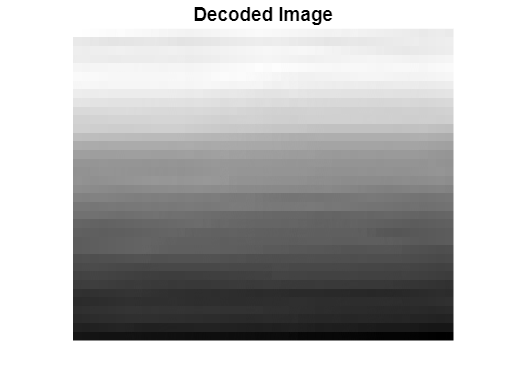

figure;
imshow(decodedImg, []);
title('Decoded Image');

function [imgBitStream, imgPSNR, decodedImg] = IntraImgEncoder(img, params, lambda)
    % Initialize variables
    img = double(img) - 128;
    previousDC = 0;
    imgBitStream = [];
    decodedFrameBuffer = zeros(size(img));

    % Get image size
    [nRow, nCol] = size(img);

    % Perform block-based intra coding
    for rowIndex = 1:params.blockSize:nRow
        for colIndex = 1:params.blockSize:nCol
            % Extract the current block
            currentBlock = img(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1);

            % Perform block intra coding
            [blockRate, blockimgPSNR, blockBitStream, decodedBlock] = blockIntraCoding(currentBlock, previousDC, params);

            % Update decoded frame buffer
            decodedFrameBuffer(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1) = reshape(decodedBlock, params.blockSize, params.blockSize);

            % Append block bitstream to the overall image bitstream
            imgBitStream = [imgBitStream, blockBitStream];

            % Update previous DC value
            previousDC = decodedBlock(1,1);
        end
    end

    % Add 128 to the decoded frame buffer
    decodedImg = decodedFrameBuffer + 128;

    % Compute overall bitstream rate
    bitstreamRate = numel(imgBitStream);

    % Compute overall imgPSNR
    mse = mean((img(:) - double(decodedImg(:))).^2);
    imgPSNR = 10 * log10((255*255) / mse);
end

function [imgBitStream, InterimgPSNR, decodedImg] = InterImgEncoder(img, params, lambda)
    % Init
    img = double(img) - 128;
    previousDC = 0;
    imgBitStream = [];
    decodedFrameBuffer = zeros(size(img));
    InterimgPSNR = 0;

    % Get image size
    [nRow, nCol] = size(img);

    for rowIndex = 1:params.blockSize:nRow
        for colIndex = 1:params.blockSize:nCol,
            currentBlock = img(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1);
            
            % Perform block-based intra and inter coding
            [blockRateIntra, blockPSNRIntra, blockBitStreamIntra] = blockIntraCoding(currentBlock, previousDC, params);
            [blockRateInter, blockPSNRInter, blockBitStreamInter] = blockInterCoding(currentBlock, previousDC, params.blockSize, params.blockSize, params);
            
            % Compute IntraCost and InterCost
            IntraCost = blockPSNRIntra + params.lambda * blockRateIntra;
            InterCost = blockPSNRInter + params.lambda * blockRateInter;
            
            if IntraCost < InterCost
                % Encode a mode flag
                imgBitStream = [imgBitStream, 0]; % Intra mode flag
                decodedBlock = reshape(blockIntraDecoding(blockBitStreamIntra, previousDC), [params.blockSize, params.blockSize]);
decodedFrameBuffer(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1) = decodedBlock;
            else
                imgBitStream = [imgBitStream, 1]; % Inter mode flag
                decodedFrameBuffer(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1) = blockInterDecoding(blockBitStreamInter, previousDC);
            end
            
            previousDC = decodedFrameBuffer(rowIndex, colIndex);
            
            % Accumulate the PSNR value for averaging
            InterimgPSNR = InterimgPSNR + blockPSNRInter;
        end
    end
    
    % Calculate the average PSNR
    totalBlocks = (nRow / params.blockSize) * (nCol / params.blockSize);
    InterimgPSNR = InterimgPSNR / totalBlocks;
    
    % Add 128 to the decoded frame buffer
    decodedImg = decodedFrameBuffer + 128;

    % Compute overall bitstream rate
    bitstreamRate = numel(imgBitStream);

    % Compute overall imgPSNR
    mse = mean((img(:) - double(decodedImg(:))).^2);
    imgPSNR = 10 * log10((255*255) / mse);

end

function [blockRateInter, blockPSNRInter, blockBitStreamInter] = blockInterCoding(currentBlock, previousDC, blockSize, Searchradius, params)
    % Motion estimation
    mvf = me(currentBlock, previousDC, blockSize, blockSize, params.Searchradius);

    % Motion compensation
    motionCompensatedBlock = mc(previousDC, mvf);

    % Compute the difference (residual) between current block and motion-compensated block
    residualBlock = currentBlock - motionCompensatedBlock;

    % Apply transform to the residual block (e.g., DCT)
    transformedBlock = dct2(residualBlock);

    % Encode the transformed block using entropy coding (e.g., Exp-Golomb coding)
    blockBitStreamInter = expGolombSigned(transformedBlock);
    blockRateInter = numel(blockBitStreamInter);
    
    % Decode the transformed block using entropy decoding
    decodedTransformedBlock = expGolombSignedDecode(blockBitStreamInter);

    % Apply inverse transform to the decoded transformed block (e.g., inverse DCT)
    inverseTransformedBlock = idct2(decodedTransformedBlock);

    % Reconstruct the motion-compensated block by adding the inverse transformed block to the motion-compensated block
    resizedInverseTransformedBlock = imresize(inverseTransformedBlock, size(motionCompensatedBlock));
    reconstructedBlock = motionCompensatedBlock + resizedInverseTransformedBlock;

    % Calculate the PSNR between the current block and the reconstructed block
    mse = mean((currentBlock(:) - reconstructedBlock(:)).^2);
    blockPSNRInter = 10 * log10((255*255) / mse);
end

function [decodedBlock] = blockIntraDecoding(blockBitStream, previousDC)
    % Decode the block bitstream using entropy decoding
    decodedTransformedBlock = expGolombSignedDecode(blockBitStream);

    % Apply inverse transform to the decoded transformed block (e.g., inverse DCT)
    inverseTransformedBlock = idct2(decodedTransformedBlock);

    % Add the previous DC value to the first element of the inverse transformed block
    decodedBlock = inverseTransformedBlock + previousDC;
end

function [blockRate, blockPSNR, blockBitStream, decodedBlock] = blockIntraCoding(currentBlock, previousDC, params)
    % Apply transform to the current block (e.g., DCT)
    transformedBlock = dct2(currentBlock);

    % Quantize the transformed block
    quantizedBlock = round(transformedBlock / params.quantizationStep);

    % Encode the quantized block using entropy coding (e.g., Exp-Golomb coding)
    blockBitStream = expGolombSigned(quantizedBlock(:));
    blockRate = length(blockBitStream);

    % Decode the quantized block using entropy decoding
    decodedQuantizedBlock = expGolombSignedDecode(blockBitStream);

    % Dequantize the decoded quantized block
    dequantizedBlock = decodedQuantizedBlock * params.quantizationStep;

    % Apply inverse transform to the dequantized block (e.g., inverse DCT)
    decodedBlock = idct2(dequantizedBlock);

    % Add the previous DC value to the first element of the decoded block
    decodedBlock(1, 1) = decodedBlock(1, 1) + previousDC;

    % Calculate the PSNR between the current block and the decoded block
    mse = mean((currentBlock(:) - decodedBlock(:)).^2);
    blockPSNR = 10 * log10((255*255) / mse);
end

function [mvf] = me(currentBlock, previousDC, blockSizeRow, blockSizeCol, Searchradius)
    [nRow, nCol] = size(currentBlock);
    mvf = zeros(nRow, nCol, 2); % Initialize motion vector field

    % Calculate the search range
    searchRange = Searchradius;

    for i = 1:blockSizeRow:nRow
        for j = 1:blockSizeCol:nCol
            % Extract the current macroblock
            currentMacroblock = currentBlock(i:i+blockSizeRow-1, j:j+blockSizeCol-1);

            % Initialize the best matching error and motion vector
            bestError = Inf;
            bestMotionVector = [0, 0];

            % Search for the best matching block in the search range
            for k = -searchRange:searchRange
                for l = -searchRange:searchRange
                                        % Calculate the coordinates of the reference block
                    refRow = i + k;
                    refCol = j + l;

                    % Check if the reference block is within the image boundaries
                    if refRow >= 1 && refRow + blockSizeRow - 1 <= nRow && refCol >= 1 && refCol + blockSizeCol - 1 <= nCol
                        % Extract the reference macroblock
                        refMacroblock = currentBlock(refRow:refRow+blockSizeRow-1, refCol:refCol+blockSizeCol-1);

                        % Calculate the error between the current macroblock and the reference macroblock
                        error = sum(sum(abs(currentMacroblock - refMacroblock)));

                        % Update the best matching error and motion vector if a better match is found
                        if error < bestError
                            bestError = error;
                            bestMotionVector = [k, l];
                        end
                    end
                end
            end

            % Store the best motion vector in the motion vector field
            mvf(i:i+blockSizeRow-1, j:j+blockSizeCol-1, 1) = repmat(bestMotionVector(1), blockSizeRow, blockSizeCol);
mvf(i:i+blockSizeRow-1, j:j+blockSizeCol-1, 2) = repmat(bestMotionVector(2), blockSizeRow, blockSizeCol);
        end
    end
end

function [motionCompensatedBlock] = mc(previousDC, mvf)
    [nRow, nCol, ~] = size(mvf);
    motionCompensatedBlock = zeros(nRow, nCol);

    for i = 1:nRow
        for j = 1:nCol
            % Calculate the coordinates of the reference block
            refRow = i + mvf(i, j, 1);
            refCol = j + mvf(i, j, 2);

            % Check if the reference block is within the image boundaries
            if refRow >= 1 && refRow <= nRow && refCol >= 1 && refCol <= nCol
                % Copy the corresponding pixel from the reference block to the motion-compensated block
                motionCompensatedBlock(i, j) = motionCompensatedBlock(refRow, refCol);
            else
                % If the reference block is outside the image boundaries, use the previous DC value as a substitute
                motionCompensatedBlock(i, j) = previousDC;
            end
        end
    end
end

% Exp-Golomb coding for signed integers
function [bitstream] = expGolombSigned(data)
    data = data(:);
    bitstream = [];

    for i = 1:numel(data)
        num = data(i);

        % Convert the signed integer to a positive integer
        if num < 0
            num = (-num) * 2 - 1;
        else
            num = num * 2;
        end

        % Encode the positive integer using Golomb coding
        quotient = floor(num / 2);
        remainder = mod(num, 2);

        unary = repmat('1', 1, quotient);
        binary = dec2bin(remainder);

        bitstream = [bitstream, unary, '0', binary];
    end
end

% Exp-Golomb decoding for signed integers
function [data] = expGolombSignedDecode(bitstream)
    data = [];

    while ~isempty(bitstream)
        % Find the first zero bit in the bitstream
        zeroIndex = find(bitstream == '0', 1);

        % Extract the unary code
        unary = bitstream(1:zeroIndex-1);
        bitstream = bitstream(zeroIndex+1:end);

        % Count the number of ones in the unary code
                numOnes = sum(unary == '1');

        % Determine the quotient and remainder
        quotient = numOnes;
        remainder = bin2dec(bitstream(1));

        % Remove the processed bits from the bitstream
        bitstream = bitstream(2:end);

        % Convert the positive integer back to a signed integer
        if rem(quotient, 2) == 1
            num = -(quotient + 1) / 2;
        else
            num = quotient / 2;
        end

        % Append the signed integer to the data
        data = [data; num];
    end
end